This scrip try to plot saved MSD data.

timestep=100;
simu_number=300;
totel_length=100;
head_index=1;
tail_index=100;

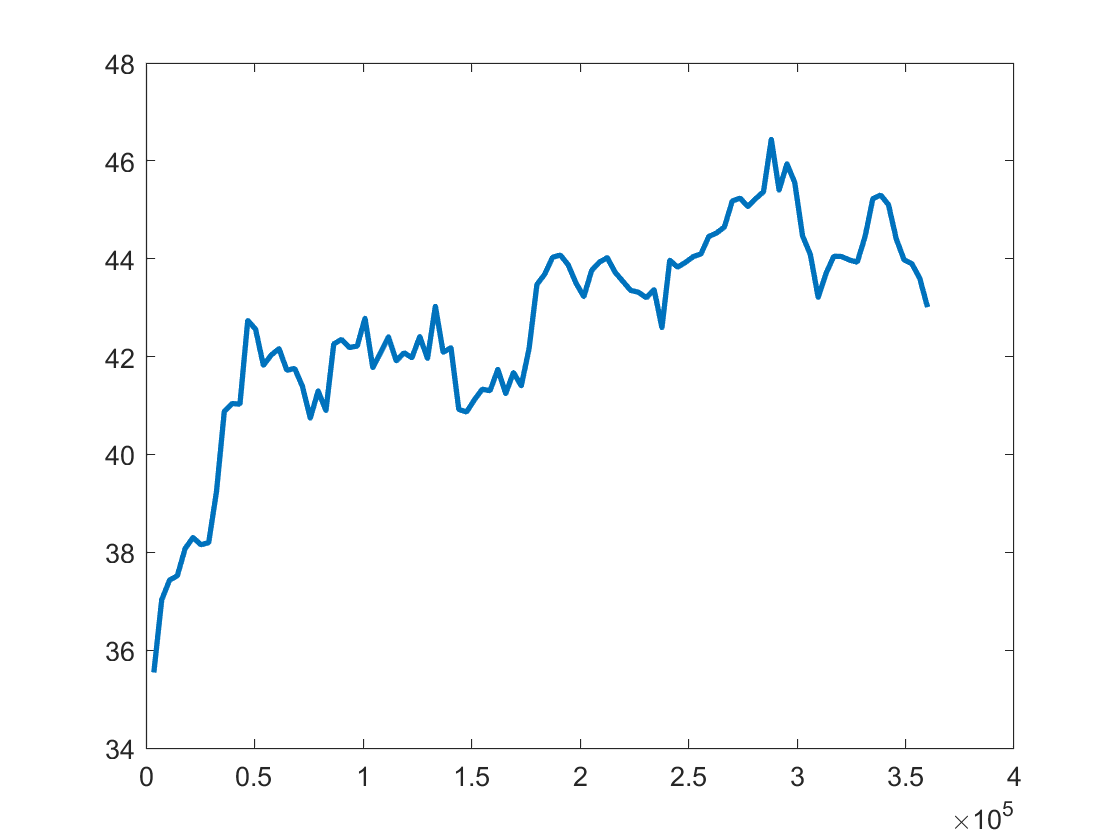

figure
%disp1='bondTight \sigma_a=0.01';
%disp1='angleFlex k=0.3';
disp1='crossLess trunc=10';
%disp1='A=0.0,num2str(totel_length),' [',num2str(head_index),'-',num2str(tail_index),'] ']
%disp1='a=2A.U.';
%disp1='k=0.01';
%disp1='L=100 [1-100]'
plot(average_time_list(1,:),MSD_average,"LineWidth",2,'DisplayName',disp1)
hold on

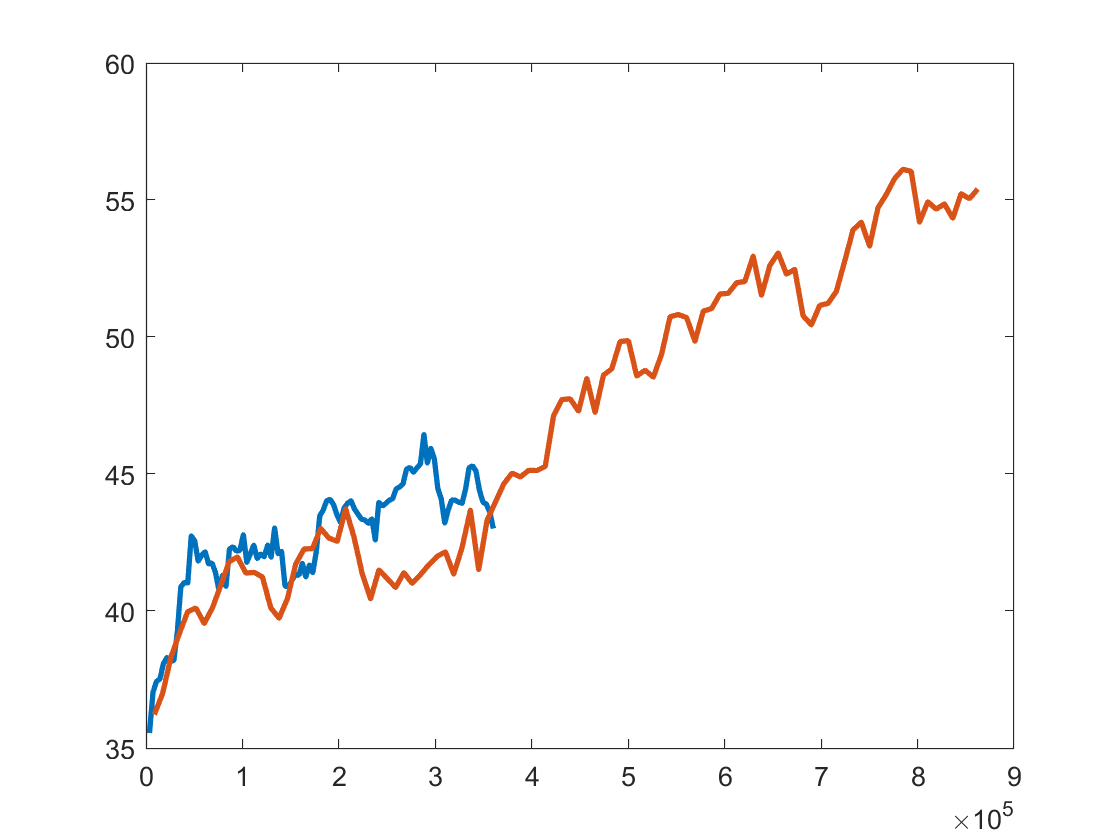

%disp2='normal \sigma_a=0.05';
%disp2='normal k=1.5';
disp2='nromal trunc=1.0';
%disp2='A=0.02';
%disp2=['L=',num2str(totel_length),' [',num2str(head_index),'-',num2str(tail_index),'] ']
%disp2='a=5A.U.';
%disp2='k=0.02';
%isp2='L=500 [201-300]';
plot(average_time_list(1,:),MSD_average,"LineWidth",2,'DisplayName',disp2)

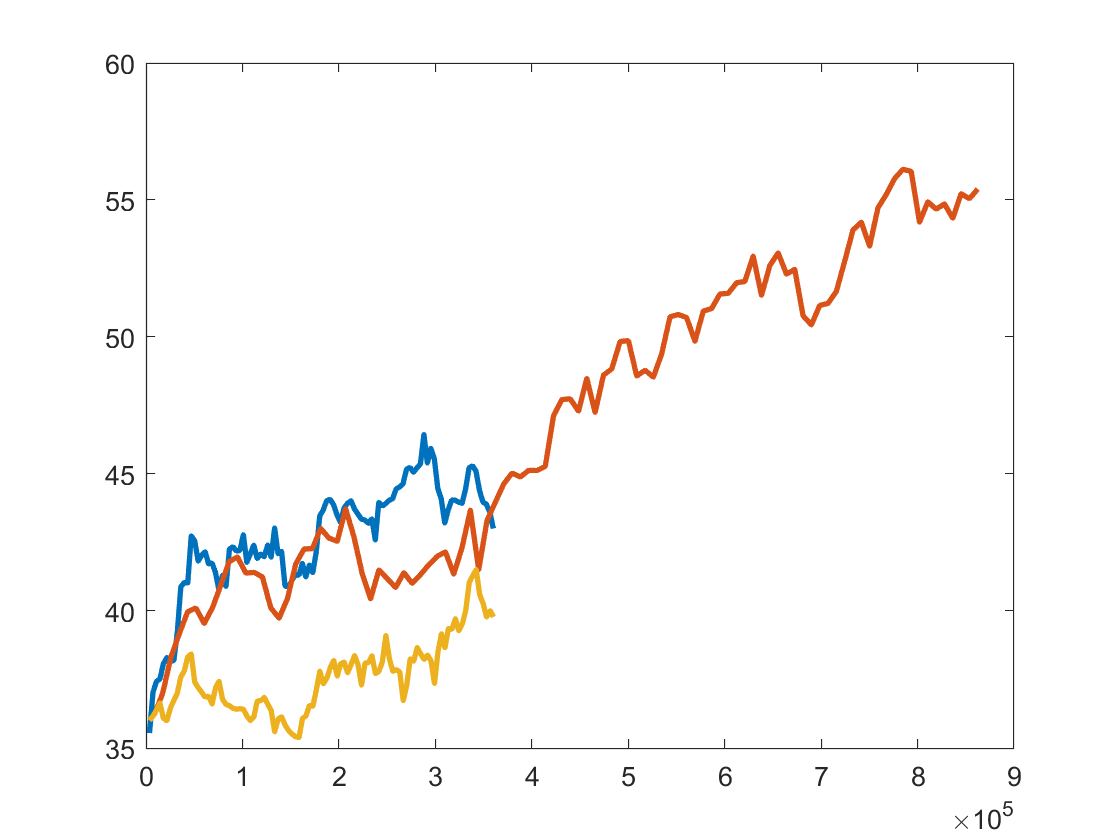

%disp3='bondLoose \sigma_a=0.25';
%disp3='angleStiff k=7.5';
disp3='crossMore trunc=0.1';
%disp3='A=0.03';
%disp3='a=10A.U.';
%disp3='k=0.03';
%disp3='L=1000 [451-550]'
plot(average_time_list(1,:),MSD_average,"LineWidth",2,'DisplayName',disp3)

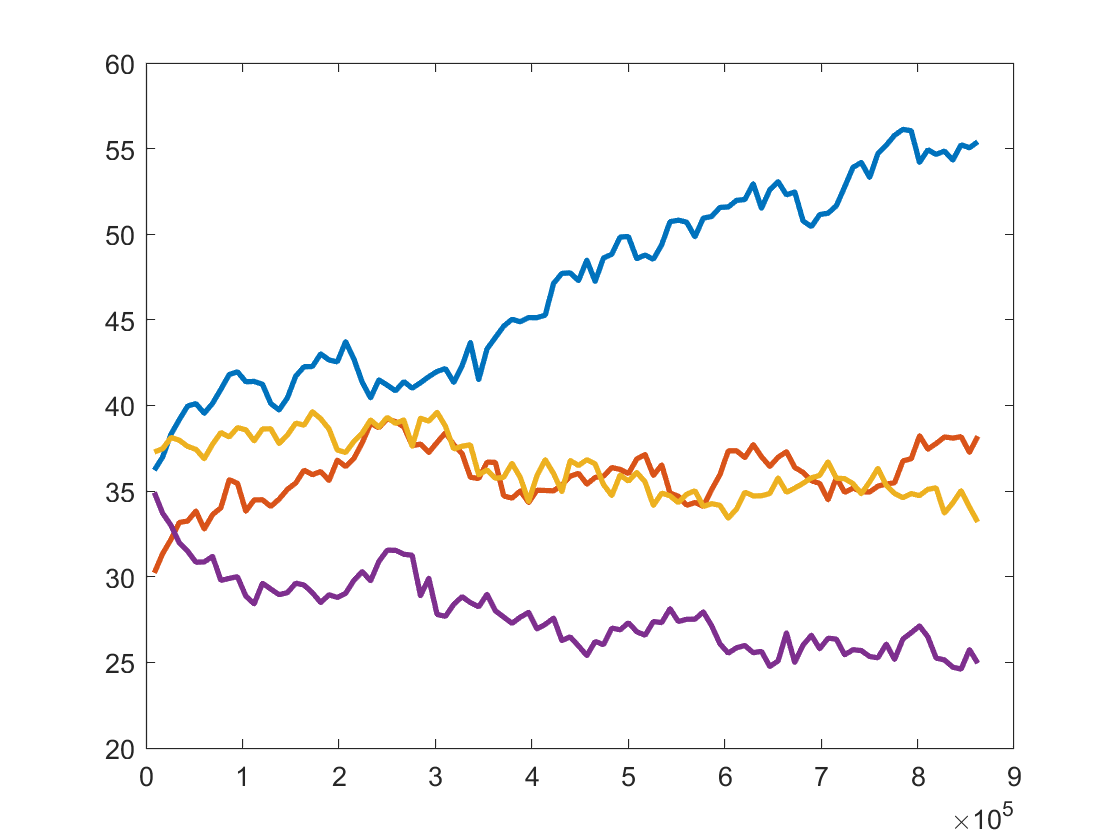

%disp4='A=0.05';
%disp4='a=20A.U.';
disp4='k=0.05';
plot(average_time_list(1,:),MSD_average,"LineWidth",2,'DisplayName',disp4)

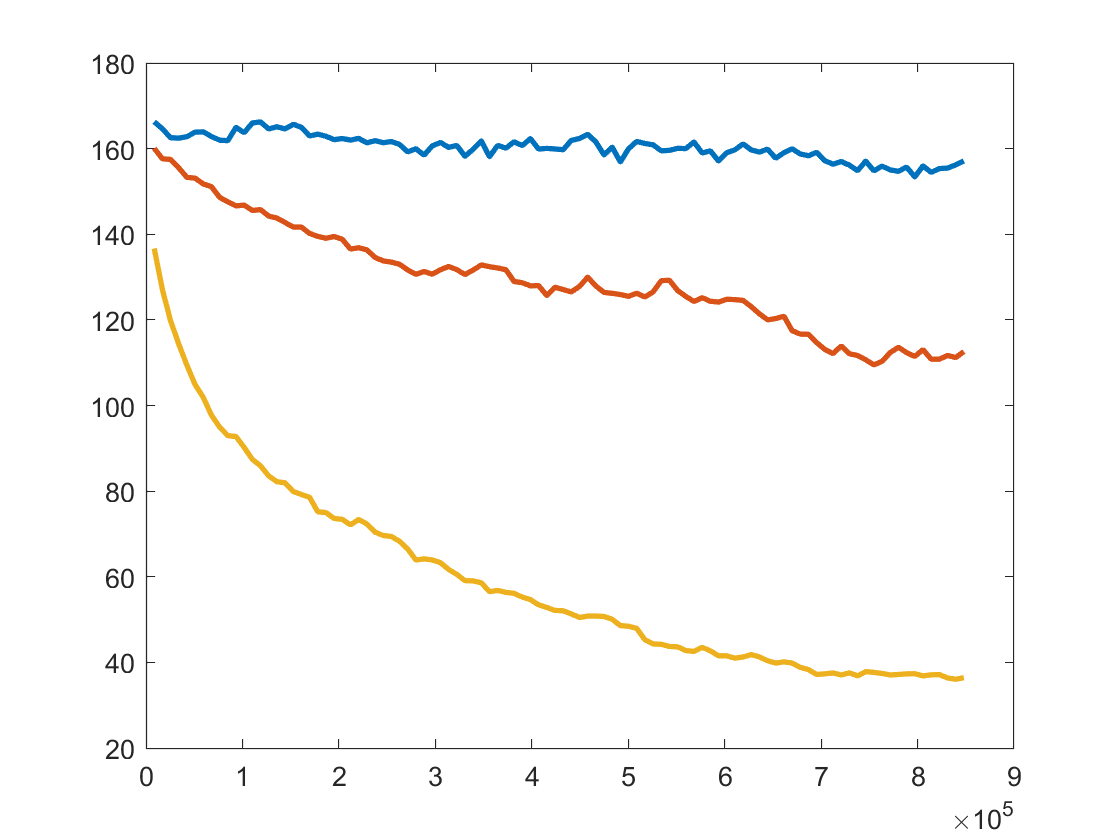

%disp5='A=0.1';
%disp5=['L=',num2str(totel_length),' [',num2str(head_index),'-',num2str(tail_index),'] ']
%disp5='a=50A.U.';
disp5='k=0.1';
plot(average_time_list(1,:),MSD_average,"LineWidth",2,'DisplayName',disp5)

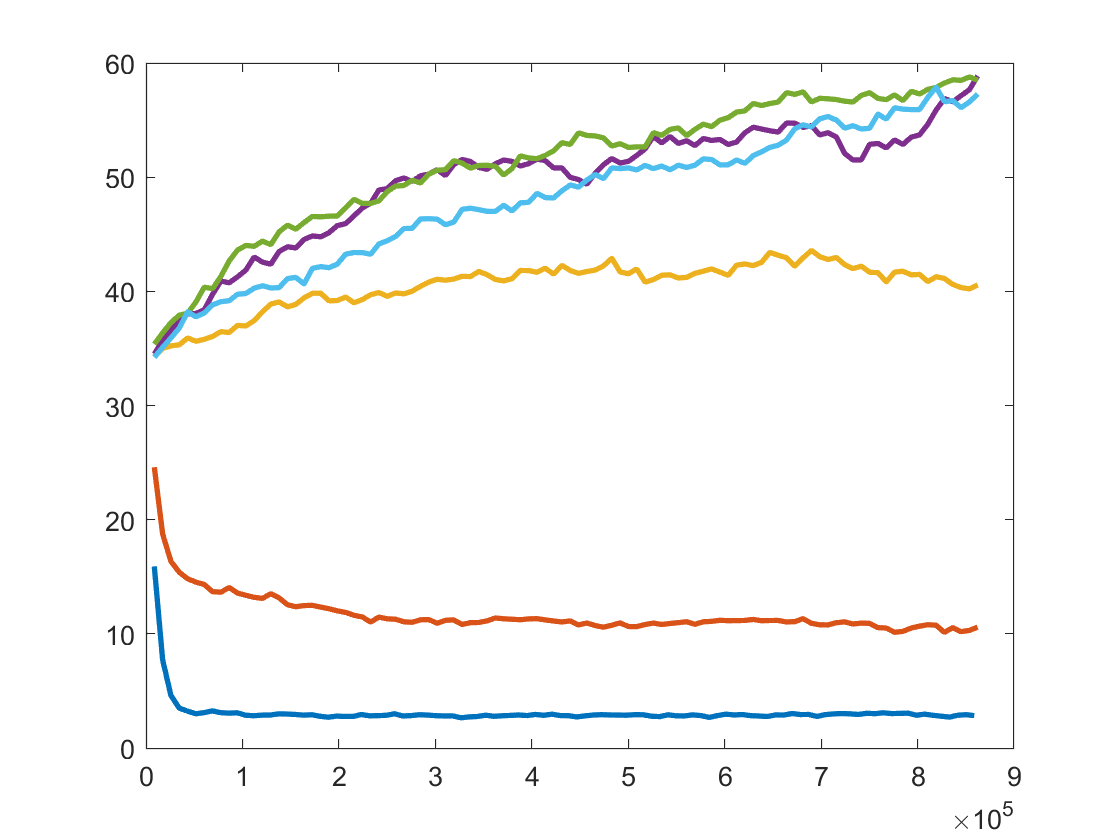

disp6='a=100A.U.';
%disp6='k=0.75'
plot(average_time_list(1,:),MSD_average,"LineWidth",2,'DisplayName',disp6)

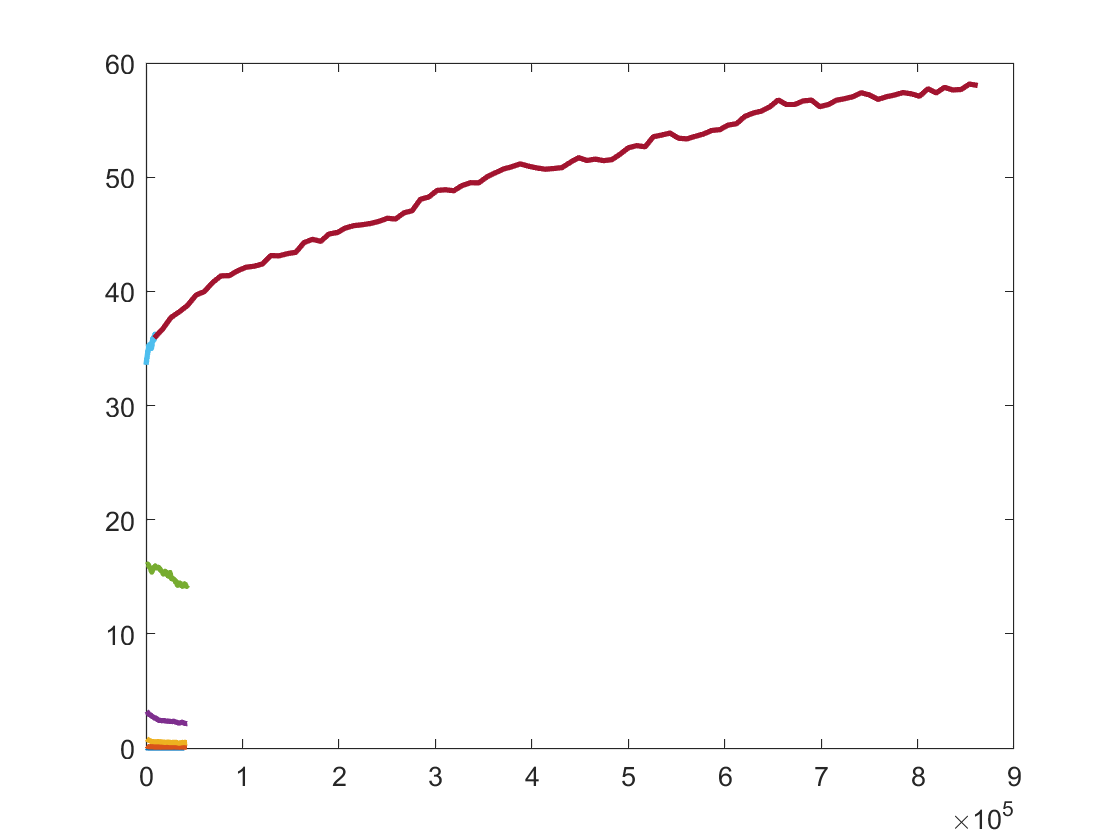

disp7='a=\infty';
plot(average_time_list(1,:),MSD_average,"LineWidth",2,'DisplayName',disp7)

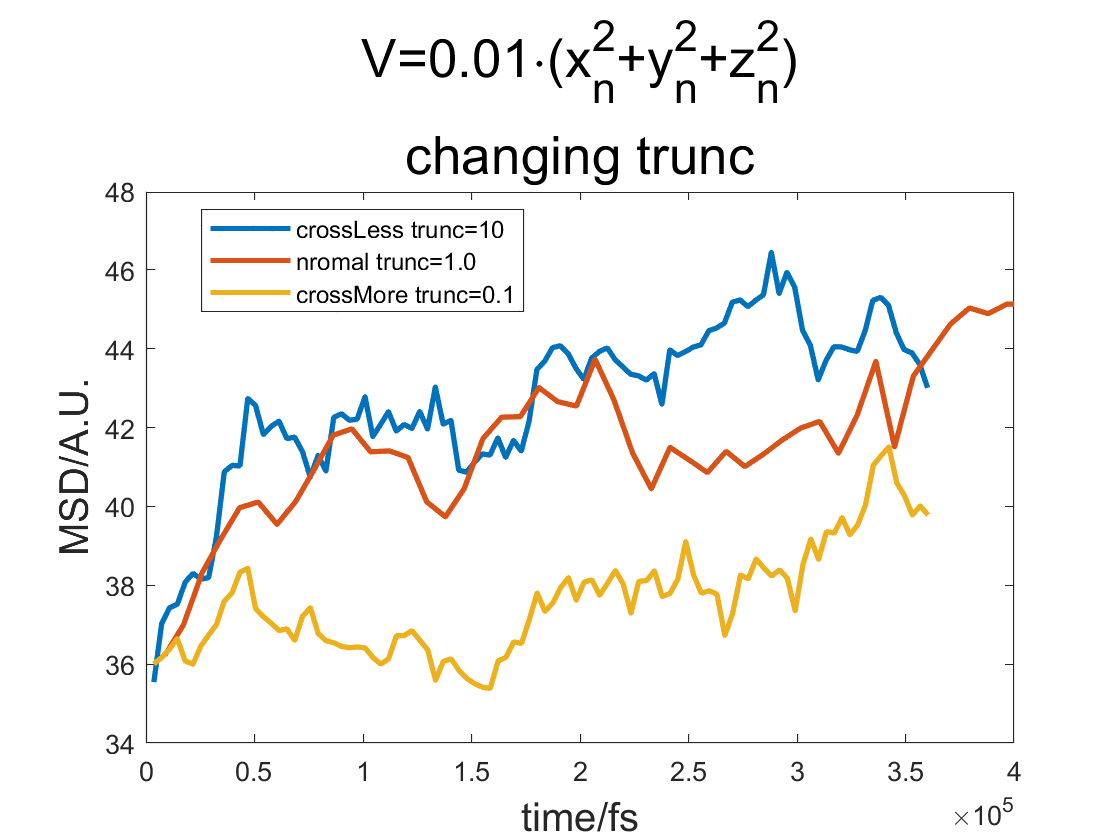

%force_field=['V=5(r_n-a)(r>a), n=',num2str(head_index),', ',num2str(tail_index)];
force_field=['V=0.01\cdot(x_n^2+y_n^2+z_n^2)'];%, n=',num2str(head_index),', ',num2str(tail_index)];
%force_field='V=0';
%force_field=['V=k\cdot(re-rp)^2'];
time_step_str='1000vlt';
%force_field=['$$V(x,y,z)=\left\{\begin{array}{lr}(5\sqrt{x^2+y^2+z^2}-R),&r\geq R \\0,&r<R\end{array}\right.$$n=',num2str(head_index),', ',num2str(tail_index)];
legend("Location","best");
xlabel('time/fs',"FontSize",15)
ylabel('MSD/A.U.',"FontSize",15)
%set(gca,'yscale','log')
%set(gca,'xscale','log')
xlim([0 4e5])
%ylim([34 48]);
title({force_field;'changing trunc'},"fontsize",20)

%title('')